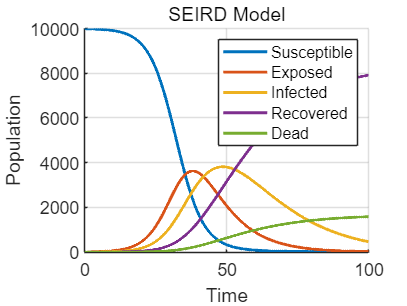

clc, clear, close all

% 设置SEIRD模型参数
params = struct();
params.N = 10000;     % 总人口
params.r_b1 = 0.3;    % 感染者传播率
params.r_b2 = 0.2;    % 潜伏者传播率
params.a = 0.1;       % 潜伏期转为感染的速率
params.gamma = 0.05;  % 恢复率
params.alpha = 0.01;  % 死亡率

% 设置初始条件
S0 = 9990;  % 初始易感人群数量（Susceptible）
E0 = 5;     % 初始潜伏人群数量（Exposed）
I0 = 5;     % 初始感染人群数量（Infected）
R0 = 0;     % 初始康复人群数量（Recovered）
D0 = 0;     % 初始死亡人数（Dead）
y0 = [S0; E0; I0; R0; D0];  % 初始状态向量

% 设置时间参数
tspan = [0, 100];  % 模拟时间范围
n = 1000;          % 时间步数

% 使用修改后的Runge-Kutta4方法求解微分方程
% [t, y] = eulerBackward(@(t,y) seirModel(t,y,params), tspan, y0, n);
% [t, y] = eulerExplicit(@(t,y) seirModel(t,y,params), tspan, y0, n);
% [t, y] = eulerImproved(@(t,y) seirModel(t,y,params), tspan, y0, n);
% [t, y] = eulerTrapezoidal(@(t,y) seirModel(t,y,params), tspan, y0, n);
[t, y] = rungeKutta4(@(t,y) seirModel(t,y,params), tspan, y0, n);

% 绘制结果
figure;
hold on;

% 绘制每个群体的曲线
plot(t, y(1, :), 'LineWidth', 2, 'DisplayName', 'Susceptible');
plot(t, y(2, :), 'LineWidth', 2, 'DisplayName', 'Exposed');
plot(t, y(3, :), 'LineWidth', 2, 'DisplayName', 'Infected');
plot(t, y(4, :), 'LineWidth', 2, 'DisplayName', 'Recovered');
plot(t, y(5, :), 'LineWidth', 2, 'DisplayName', 'Dead');

% 设置图表标签和标题
xlabel('Time');
ylabel('Population');
title('SEIRD Model');
grid on;
legend();

% 美化图表
set(gca, 'FontSize', 12);
set(gcf, 'Color', 'w');
hold off;

function dydt = seirModel(~, y, params)
% SEIRD模型的微分方程函数

% 输入：
%   y: 当前状态向量 [S, E, I, R, D]
%   params: 包含模型参数的结构体
% 输出：
%   dydt: 状态变量的导数向量

% 解包当前状态
S = y(1);  % 易感人群
E = y(2);  % 潜伏人群
I = y(3);  % 感染人群
R = y(4);  % 康复人群
D = y(5);  % 死亡人数

% 计算各群体的变化率
dSdt = -(params.r_b1*I*S)/params.N - (params.r_b2*E*S)/params.N;  % 易感人群减少率
dEdt = (params.r_b1*I*S)/params.N + (params.r_b2*E*S)/params.N - params.a*E;  % 潜伏人群变化率
dIdt = params.a*E - params.gamma*I - params.alpha*I;  % 感染人群变化率
dRdt = params.gamma*I;  % 康复人群增加率
dDdt = params.alpha*I;  % 死亡人数增加率

% 返回导数向量
dydt = [dSdt; dEdt; dIdt; dRdt; dDdt];
end